# Hausaufgabe | Projektpraktikum Matlab

## Programmiertechnik I: Anonyme Funkionen

## Gruppenmitglieder

- Mitglied 1:  Johannes Truong Le (03637523)

- Mitglied 2:  Bernhard Birkner (03637368)

- Mitglied 3:  Sebastian Getz (03623589)

## Allgemeine Hinweise

- Hausaufgaben werden in Gruppen von max. 3 Personen bearbeitet

- Eine gemeinsame Lösung pro Gruppe wird eingereicht

- Jede Datei muss die Namen aller Mitglieder im Header enthalten

- Ihre Lösung der Aufgabe ergänzen Sie in der Datei mit der Aufgabenstellung direkt unterhalb der einzelnen Teilaufgaben. Wird explizit eine Funktion gefordert, liefern Sie diese als *.m-Datei ab

- Textuelle Antworten werden als Text im Live-Editor formatiert

- Code wird im Code-Modus im Live-Editor hinzugefügt

- Abgabe der Lösung erfolgt unter [www.moodle.tum.de](http://www.moodle.tum.de)

## Aufgabenstellung

1) Erzeugen Sie für folgende mathematische Funktionen anonyme Funktionen unter Matlab

- 
$$f\left(x\right)=\sqrt{x}$$


- 
$$g\left(x\right)=a\cdot x^{2\text{  }} +b\cdot x+c$$


- 
$$h\left(x\right)=sin\left(2\pi \cdot x+\text{ }\frac{\pi }{2}\right)$$


% 3 Zufällige Zahlen für a b c im Intervall [-10,10]
a = round(rand(1)*20)-10, b = round(rand(1)*20)-10, c = round(rand(1)*20)-10 

a = 6

b = -10

c = -9

% definiere Funktionen
f = @(x) sqrt(x);
g = @(x) a*x.^2 + b*x + c;
h = @(x) sin(2*pi*x+0.5*pi);

2) Programmieren Sie eine Funktion `plot_my_function`, die einen Wertebereich von `x` und einen function_handle `f_h` einer beliebigen Funktion als Input-Argumente erhält und den Verlauf der entsprechenden Funktion über dem übergebenen Wertebereich graphisch darstellt.

Validieren Sie hierzu  `plot_my_function `für `f, g, h` über einen beispielhaften Wertebereich von `x` Ihrer Wahl. Erzeugen Sie zwei unterschiedliche Plots von `g` für unterschiedliche Parameter `a, b, c`.

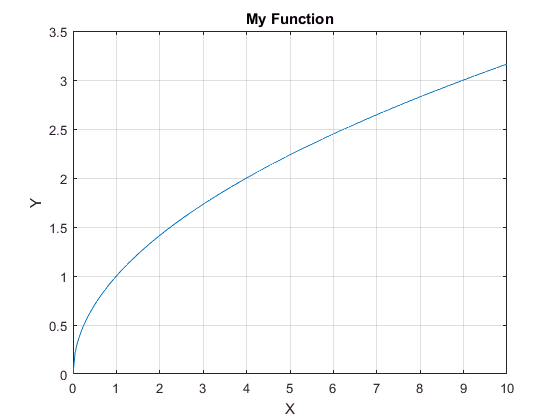

x = 0:0.05:10;

handle_f = plot_my_function(x,f);

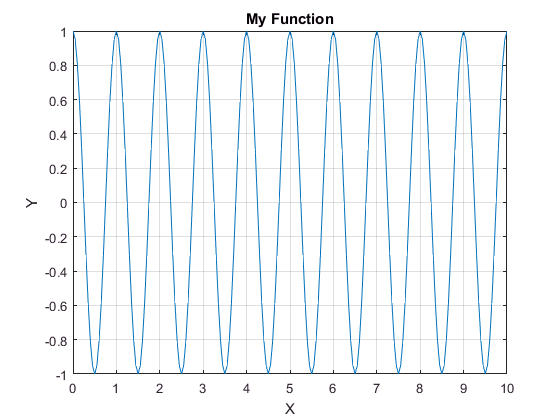

handle_h = plot_my_function(x,h);

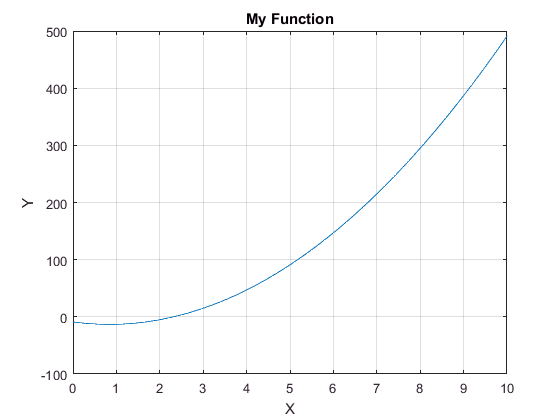

handle_g1 = plot_my_function(x,g);


% 3 neue Zufallszahlen für a,b,c im Intervall [-10,10]
a = round(rand(1)*20)-10, b = round(rand(1)*20)-10, c = round(rand(1)*20)-10

a = -7

b = 3

c = 5

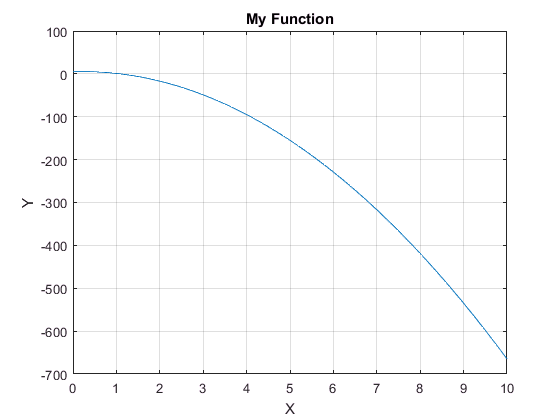

% definiere g neu
g = @(x) a*x.^2 + b*x + c;
handle_g2 = plot_my_function(x,g);


% setze Eigenschaft 'Visible', da die mlx-Datei die figures unsichtbar macht und dafür einbettet
set(handle_f, 'Visible', 'on');

Error using matlab.ui.Figure/set
While setting property 'Visible' of class 'Figure':
Value must be specified as the string 'on' or 'off'

set(handle_g1, 'Visible', 'on');
set(handle_g2, 'Visible', 'on');
set(handle_h, 'Visible', 'on');

% Speichere Figures
savefig(handle_f, 'f.fig');
savefig(handle_g1, 'g1.fig');
savefig(handle_g2, 'g2.fig');
savefig(handle_h, 'h.fig');